1 dwie różne wartości własnie rzeczywiste tego samego znaku (stabilny, niestabilny)

2. dwie wartości własne rzeczywiste przeciwnych znaków (siodło)

3 dwie wartości własne zespolone sprzężone niezerowe rzeczywiste  (ognisko asymp stab, nstab)

4. dwie wartości własne zespolone sprzężone niezerowe 

5 dwie wartości własne rzeczywiste równe, niezerowe i tylko jeden wektor własny własne liniowo niezależne

6 dwie wartości własne rzeczywiste równe, niezerowe i związane z nimi dwa wektory własne liniowo niezależne

7 dwie wartości własne rzeczywiste jedna równa zero

8 dwie wartości własne zerowe, jeden, liniowo niezależny wektor własny

9 A = 0

Punkty początkowe

X = [-1:0.2:1];
[X, Y] = meshgrid(X, X);
a = size(X);
m = a(1);
T=0.01;


A=[-2,2;1,-3];
output = ones(m,m,2);
[w, J]=eig(A); %wektory i wartości własne
for x=1:m
    for y=1:m
        x0=[X(x,y), Y(x,y)];
        out = sim('traj_fazowe',T);
        output(x,y,:) = out.x(2,:);
    end
end
quiver(X,Y,output(:,:,1)-X,output(:,:,2)-Y);
"Macierz stanu"

ans = "Macierz stanu"

A

A =     -2     2
     1    -3


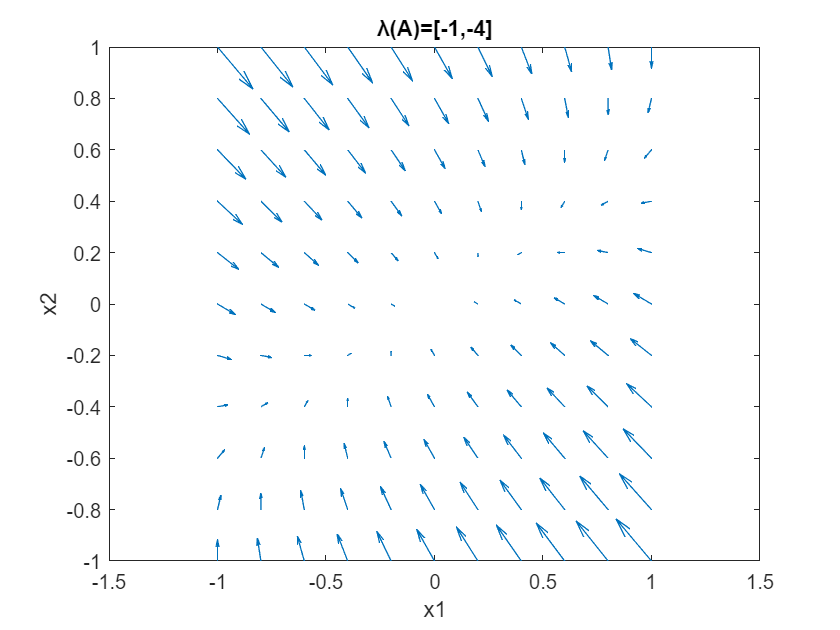


title(['\lambda(A)=[',num2str(J(1,1)),',',num2str(J(2,2)),']'] );
xlabel("x1")
ylabel("x2")

"Wektory główne"

ans = "Wektory główne"

w

w =     0.8944   -0.7071
    0.4472    0.7071


1b dwie różne wartości własnie rzeczywiste tego samego znaku dodatnie, niestabilny

na wykresie widać, iż wartości funkcji rosną do nieskończoności, a więc układ ten nie jest stabilny.

A=[1,0;0,2];
output = ones(m,m,2);
[w, J]=eig(A); %wektory i wartości własne
for x=1:m
    for y=1:m
        x0=[X(x,y), Y(x,y)];
        out = sim('traj_fazowe',T);
        output(x,y,:) = out.x(2,:);
    end
end
w

w =      1     0
     0     1


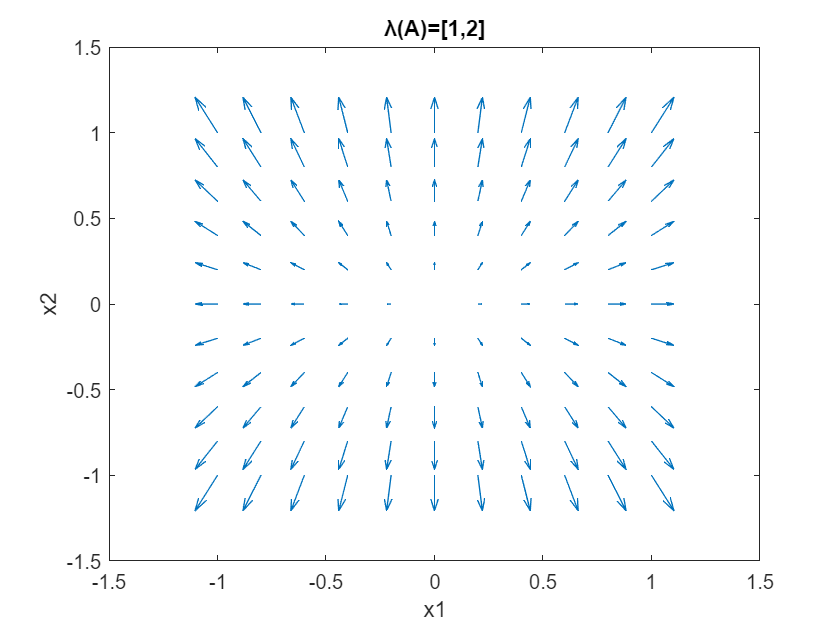

quiver(X,Y,output(:,:,1)-X,output(:,:,2)-Y);
title(['\lambda(A)=[',num2str(J(1,1)),',',num2str(J(2,2)),']'] );
xlabel("x1")
ylabel("x2")

2. dwie wartości własne rzeczywiste przeciwnych znaków (siodło)

tylko punkty położone na prostej y=0 są stabilne

A=[-2, 0 ;0, 2];
output = ones(m,m,2);
[w, J]=eig(A); %wektory i wartości własne
for x=1:m
    for y=1:m
        x0=[X(x,y), Y(x,y)];
        out = sim('traj_fazowe',T);
        output(x,y,:) = out.x(2,:);
    end
end
w

w =      1     0
     0     1


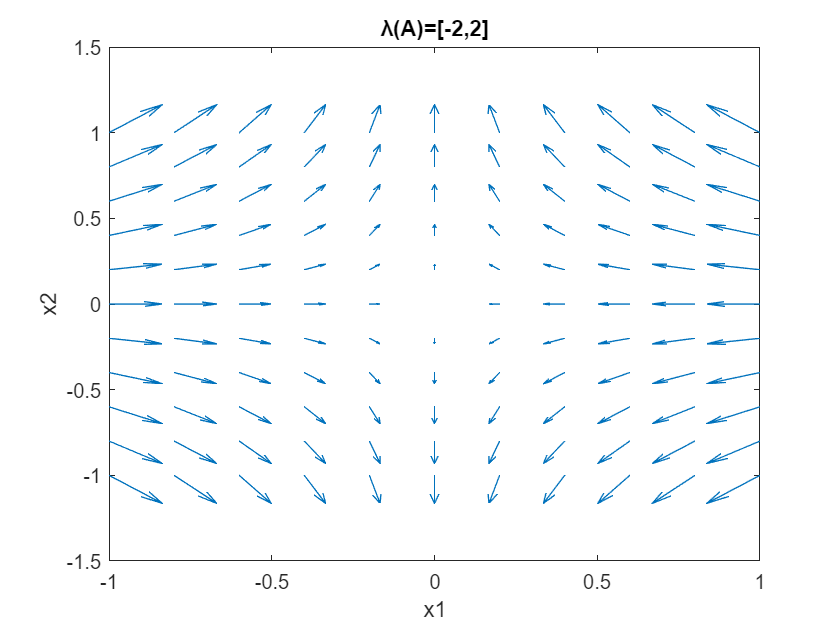

quiver(X,Y,output(:,:,1)-X,output(:,:,2)-Y);
title(['\lambda(A)=[',num2str(J(1,1)),',',num2str(J(2,2)),']'] );
xlabel("x1")
ylabel("x2")

3, 4. dwie wartości własne zespolone sprzężone niezerowe rzeczywiste

stabilność układu zależy od wartości liczb rzeczywistych - wartości dodatkowo poruszają się po "okręgach" wokół punktu (0,0), ponieważ mają część urojoną.

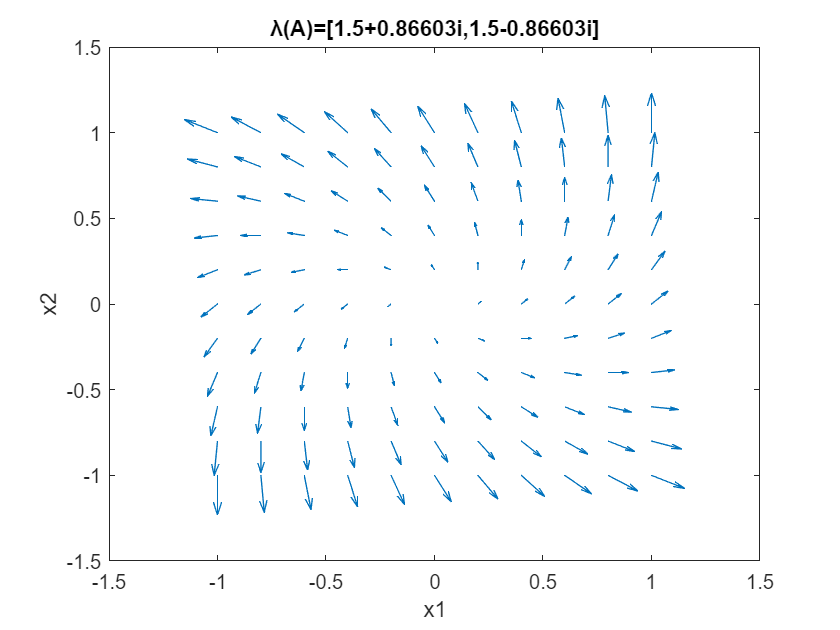

A = [1,-1;1, 2];
output = ones(m,m,2);
[w, J]=eig(A); %wektory i wartości własne
for x=1:m
    for y=1:m
        x0=[X(x,y), Y(x,y)];
        out = sim('traj_fazowe',T);
        output(x,y,:) = out.x(2,:);
    end
end
quiver(X,Y,output(:,:,1)-X,output(:,:,2)-Y);
title(['\lambda(A)=[',num2str(J(1,1)),',',num2str(J(2,2)),']'] );
xlabel("x1")
ylabel("x2")

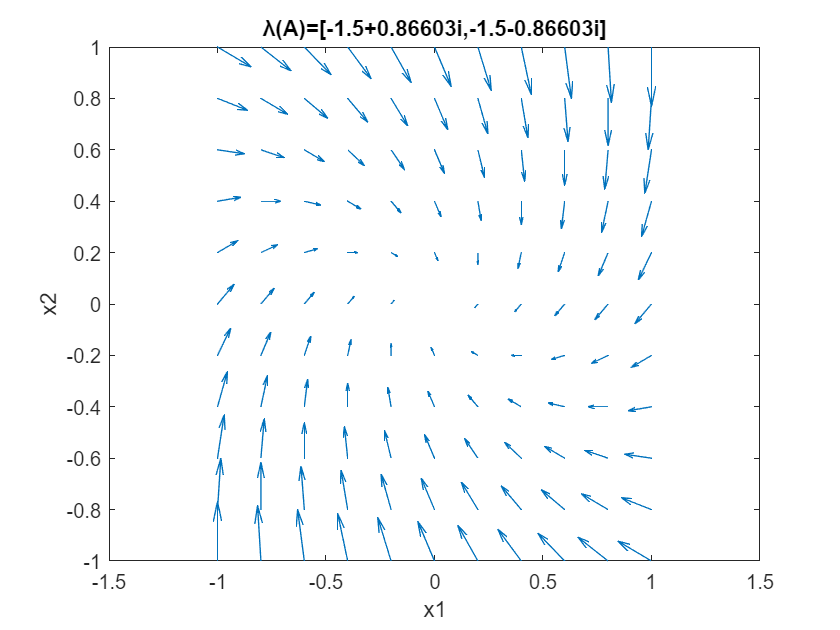

A = [-1,1;-1, -2];
output = ones(m,m,2);
[w, J]=eig(A); %wektory i wartości własne
for x=1:m
    for y=1:m
        x0=[X(x,y), Y(x,y)];
        out = sim('traj_fazowe',T);
        output(x,y,:) = out.x(2,:);
    end
end
quiver(X,Y,output(:,:,1)-X,output(:,:,2)-Y);
title(['\lambda(A)=[',num2str(J(1,1)),',',num2str(J(2,2)),']'] );
xlabel("x1")
ylabel("x2")

A = [0,-1;1, 0];
output = ones(m,m,2);
[w, J]=eig(A); %wektory i wartości własne
for x=1:m
    for y=1:m
        x0=[X(x,y), Y(x,y)];
        out = sim('traj_fazowe',T);
        output(x,y,:) = out.x(2,:);
    end
end
quiver(X,Y,output(:,:,1)-X,output(:,:,2)-Y);
title(['\lambda(A)=[',num2str(J(1,1)),',',num2str(J(2,2)),']'] );
xlabel("x1")
ylabel("x2")

5 dwie wartości własne rzeczywiste równe, niezerowe i tylko jeden wektor własny własne liniowo niezależne 

zbieżny asymptotycznie dla wartości ujemnych, rozbieżny dla dodatnich, lekko skręca.

A=[-1,1;0,-1];
output = ones(m,m,2);
[w, J]=eig(A); %wektory i wartości własne
for x=1:m
    for y=1:m
        x0=[X(x,y), Y(x,y)];
        out = sim('traj_fazowe',T);
        output(x,y,:) = out.x(2,:);
    end
end
quiver(X,Y,output(:,:,1)-X,output(:,:,2)-Y);
w

w =     1.0000   -1.0000
         0    0.0000


title(['\lambda(A)=[',num2str(J(1,1)),',',num2str(J(2,2)),']'] );
xlabel("x1")
ylabel("x2")

6 dwie wartości własne rzeczywiste równe, niezerowe i związane z nimi dwa wektory własne liniowo niezależne

zachowuje się jakby były to dwie różne wartości własne.

A=[2,0;0,2];
output = ones(m,m,2);
[w, J]=eig(A); %wektory i wartości własne
for x=1:m
    for y=1:m
        x0=[X(x,y), Y(x,y)];
        out = sim('traj_fazowe',T);
        output(x,y,:) = out.x(2,:);
    end
end
quiver(X,Y,output(:,:,1)-X,output(:,:,2)-Y);
w

w =      1     0
     0     1


title(['\lambda(A)=[',num2str(J(1,1)),',',num2str(J(2,2)),']'] );
xlabel("x1")
ylabel("x2")

7 dwie wartości własne rzeczywiste jedna równa zero

przemieszcza się tylko w jednym kierunku, tylko zwrot wektorów przemieszczenia może się zmienić.. wartość wektora zmienia się wraz z przemieszczeniem w tym kierunku, nie zmienia się podczas przemieszczania w kierunku prostopadłym do niego.

A=[1,0;0,0];
output = ones(m,m,2);
[w, J]=eig(A); %wektory i wartości własne
for x=1:m
    for y=1:m
        x0=[X(x,y), Y(x,y)];
        out = sim('traj_fazowe',T);
        output(x,y,:) = out.x(2,:);
    end
end
quiver(X,Y,output(:,:,1)-X,output(:,:,2)-Y);
w

w =      0     1
     1     0


title(['\lambda(A)=[',num2str(J(1,1)),',',num2str(J(2,2)),']'] );
xlabel("x1")
ylabel("x2")

8 dwie wartości własne zerowe, jeden, liniowo niezależny wektor własny

przemieszcza się tylko w jednym kierunku, tylko zwrot wektorów przemieszczenia może się zmienić. Wartość wektora nie zmienia się wraz z przemieszczeniem w tym kierunku. Zmienia się ono podczas przemieszczania w kierunku prostopadłym do niego.

A=[0,1;0,0];
output = ones(m,m,2);
[w, J]=eig(A); %wektory i wartości własne
for x=1:m
    for y=1:m
        x0=[X(x,y), Y(x,y)];
        out = sim('traj_fazowe',T);
        output(x,y,:) = out.x(2,:);
    end
end
quiver(X,Y,output(:,:,1)-X,output(:,:,2)-Y);
w

w =     1.0000   -1.0000
         0    0.0000


title(['\lambda(A)=[',num2str(J(1,1)),',',num2str(J(2,2)),']'] );
xlabel("x1")
ylabel("x2")

9 A = 0

układ pozostaje w miejscu, w którym był.

A=[0,0;0,0];
output = ones(m,m,2);
[w, J]=eig(A); %wektory i wartości własne
for x=1:m
    for y=1:m
        x0=[X(x,y), Y(x,y)];
        out = sim('traj_fazowe',T);
        output(x,y,:) = out.x(2,:);
    end
end
quiver(X,Y,output(:,:,1)-X,output(:,:,2)-Y);
w

w =      1     0
     0     1


title(['\lambda(A)=[',num2str(J(1,1)),',',num2str(J(2,2)),']'] );
xlabel("x1")
ylabel("x2")

syms t; 
A=[0,1;-1,0]

A =      0     1
    -1     0


[w, J]=eig(A)

w =    0.7071 + 0.0000i   0.7071 + 0.0000i
   0.0000 + 0.7071i   0.0000 - 0.7071i


J =    0.0000 + 1.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 - 1.0000i


expm(A*t)

$$ans = \left(\begin{array}{cc} \frac{{\mathrm{e}}^{-t\,\mathrm{i}}}{2}+\frac{{\mathrm{e}}^{t\,\mathrm{i}}}{2} & \frac{{\mathrm{e}}^{-t\,\mathrm{i}}\,\mathrm{i}}{2}-\frac{{\mathrm{e}}^{t\,\mathrm{i}}\,\mathrm{i}}{2}\\ -\frac{{\mathrm{e}}^{-t\,\mathrm{i}}\,\mathrm{i}}{2}+\frac{{\mathrm{e}}^{t\,\mathrm{i}}\,\mathrm{i}}{2} & \frac{{\mathrm{e}}^{-t\,\mathrm{i}}}{2}+\frac{{\mathrm{e}}^{t\,\mathrm{i}}}{2} \end{array}\right)$$

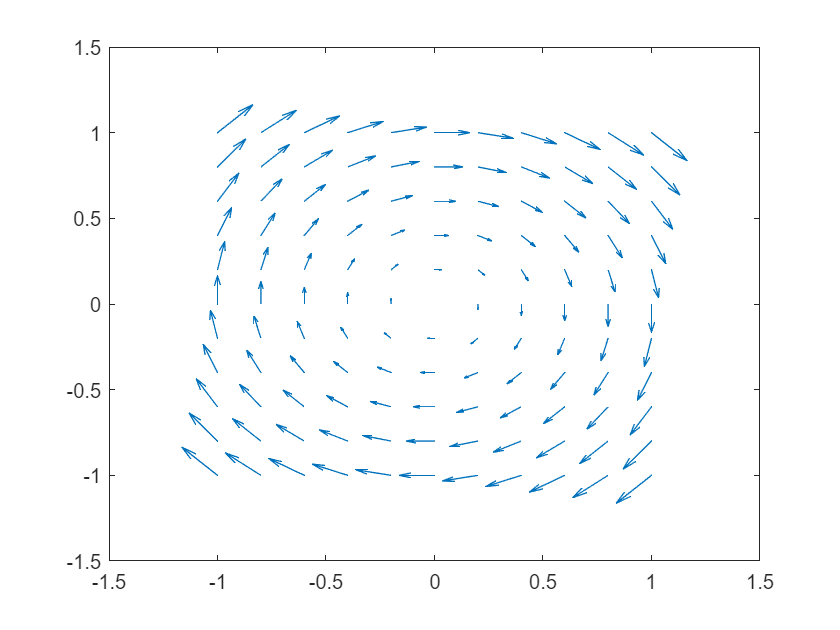

[w, J]=eig(A); %wektory i wartości własne
for x=1:m
    for y=1:m
        x0=[X(x,y), Y(x,y)];
        out = sim('traj_fazowe',T);
        output(x,y,:) = out.x(2,:);
    end
end
quiver(X,Y,output(:,:,1)-X,output(:,:,2)-Y);

w

w =    0.7071 + 0.0000i   0.7071 + 0.0000i
   0.0000 + 0.7071i   0.0000 - 0.7071i
